Maximum F = 436.2𝑘𝑁

clear all
clf

N_top = 2.130e5;%2.1499e5; %N
M_top = 10.12; %11.638; %Nm
N_midt = 2.395e5;%2.4088e5; %N
M_midt = 86.88;%85.326; %Nm
N_bot = 2.372e5; %2.3954e5; %N
M_bot = 88.05; %86.191; %Nm

N_max = [N_top, N_midt, N_bot];
M_max = [M_top, M_midt, M_bot];
% d = 0.024; %m bolt diameter

 Look up value in table

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
d = sqrt(A_t*4/pi)

d =        0.0212


S_N1_max = N_max/A_t

S_N1_max =     6.034e+08   6.7847e+08   6.7195e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2_max = M_max * y / I

S_N2_max =    1.0818e+07   9.2874e+07   9.4124e+07



S_max = S_N1_max + S_N2_max

S_max =    6.1422e+08   7.7134e+08   7.6608e+08


Minimum F = 43.6𝑘𝑁

N_top = 2.132e5;%2.0714e5; %N
M_top = 1.448;%2.8462; %Nm
N_midt = 2.122e5;%2.0631e5; %N
M_midt = 1.559;%3.1656; %Nm
N_bot = 2.124e5;%2.0675e5; %N
M_bot = 5.849;%5.7774; %Nm

N_min = [N_top, N_midt, N_bot];
M_min = [M_top, M_midt, M_bot];

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
% d = 0.024; %m bolt diameter
d = sqrt(A_t*4/pi)

d =        0.0212


% A_test = pi*(d/2)^2
S_N1_min = N_min/A_t

S_N1_min =    6.0397e+08   6.0113e+08    6.017e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2_min = M_min * y / I

S_N2_min =    1.5479e+06   1.6666e+06   6.2525e+06



S_min = S_N1_min + S_N2_min

S_min =    6.0551e+08    6.028e+08   6.0795e+08


Stress range $\Delta\sigma$

DS = S_max - S_min %stress range Pa

DS =    8.7037e+06   1.6854e+08   1.5813e+08


Den mest kritiske bolt er midter bolten da den har størst stress range

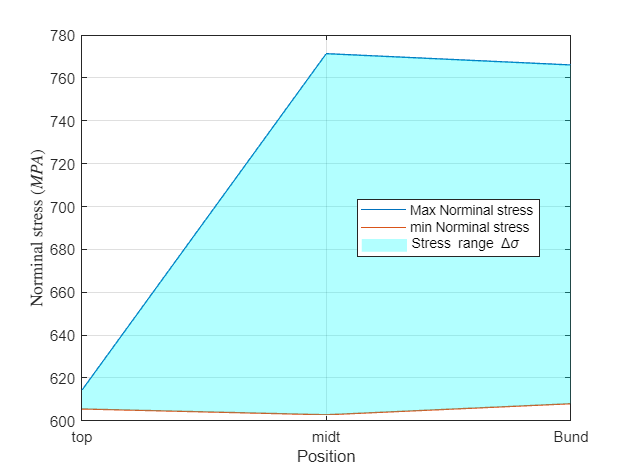

figure(1)
pos = [1,2,3];
plot(pos,S_max/1e6, DisplayName='Max Norminal stress')
hold on
plot(pos,S_min/1e6, DisplayName='min Norminal stress')
fill([pos fliplr(pos)], [S_max fliplr(S_min)]/1e6, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none', DisplayName='Stress range \Delta\sigma')
xlabel('Position')
ylabel('Norminal stress ($MPA$)', Interpreter='latex')
xticks(pos) % Set the positions of the xticks
xticklabels({'top', 'midt', 'Bund'}) % Set the labels for the xtickslegend(Location='best')
legend('Location', 'best')
grid('on')
hold off

curve data load 0 to 500kN

% clear all
% clf
% % Define the filename and range
% filename = 'D:\Mathias\OneDrive\Mathias uddannelse\Ingeniør\Maskinteknik\6. Semester\Avanceret udmattelseslære\Opgaver\Opgave 12\Heat exchanger experiments data.xlsx';
% % filename = 'C:\AU onedrive\OneDrive - Aarhus universitet\Varmetransmission\Heat exchanger experiments data.xlsx';
% 
% 
% range = 'G19:L19';
% exp2_test1 = xlsread(filename, range) % Import data from Excel file
clf
F = [0, 100, 200, 300, 400, 500];
N_0 = 2.200e5;	
M_0 = 2.415;%4.067;
N_100 = 2.127e5; %2.056e5;	
M_100 = 1.886; %2.707;
N_200 = 2.150e5; %2.084e5;	
M_200 = 11.25; %13.26;
N_300 = 2.208e5; %2.133e5;	
M_300 = 30.98; %36.24;
N_400 = 2.325e5; %2.348e5;
M_400 = 68.70; %66.35;
N_500 = 2.528e5; %2.550e5;	
M_500 = 122.9; %119.7
N = [N_0, N_100, N_200, N_300, N_400, N_500];
M = [M_0, M_100, M_200, M_300, M_400, M_500];

Fs = [43.6, 436.2]; % fra modellen

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
d = sqrt(A_t*4/pi)

d =        0.0212



S_N1 = N/A_t

S_N1 =    6.2323e+08   6.0255e+08   6.0907e+08    6.255e+08   6.5864e+08   7.1615e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 =    2.5816e+06   2.0161e+06   1.2026e+07   3.3117e+07   7.3439e+07   1.3138e+08



S = S_N1 + S_N2

S =    6.2581e+08   6.0457e+08   6.2109e+08   6.5861e+08   7.3208e+08   8.4753e+08



figure(2)
plot(F,S/1e6,'o', DisplayName='Stresses from SW test')
hold on

F_lin = linspace(0,500,100);
S_lin = interp1(F,S,F_lin, 'pchip'); % interpolere

syms x
% Manual pchip interpolation (simplified example)
% S_lin_manual = zeros(size(F_lin));
% 
% for i = 2:length(F)
%     % Linear interpolation for simplicity
%     idx = F_lin >= F(i-1) & F_lin <= F(i);
%     S_lin_manual(idx) = S(i-1) + (S(i) - S(i-1)) / (F(i) - F(i-1)) * (F_lin(idx) - F(i-1));
% end

plot(F_lin,S_lin/1e6, DisplayName='Stresses interpolated pchip')
legend(Location='Best')


p = polyfit(F,S,length(F)-1)

p =   -3.3865e-05     0.047083      -22.579       5874.5  -6.1781e+05   6.2581e+08


% [P_poly,S_pol] = polyfit(F,S,length(F)-1)
% S_poly = polyval(p, F_lin)
% plot(F_lin,S_poly/1e6, DisplayName='Stresses interpolated poly')


syms S_int_poly(x) x
S_int_poly(x) = 0;

n = length(N);
for i = 1:n
    S_int_poly(x) = S_int_poly(x) + p(i)*x^(n-i);  
end
S_int_poly_eq = vpa(S_int_poly(x),5)

$$S\_int\_poly\_eq = -0.000033865\,x^{5}+0.047083\,x^{4}-22.579\,x^{3}+5874.5\,x^{2}-617810.0\,x+6.2581e+8$$


plot(F_lin,S_int_poly(F_lin)/1e6, DisplayName='Stresses interpolated trans')

% help interp1

% S_int_pchip = interp1(F,S,Fs, 'pchip')

% S_int_poly_val = polyval(p, Fs)

% S_int_trans = double(S_int_poly(Fs))

S_min_VA = double(S_int_poly(Fs(1)))

S_min_VA =    6.0834e+08


S_min_CA = S_min(1)

S_min_CA =    6.0551e+08


S_max_VA = double(S_int_poly(Fs(2)))

S_max_VA =    7.6983e+08


S_max_CA = S_max(2)

S_max_CA =    7.7134e+08


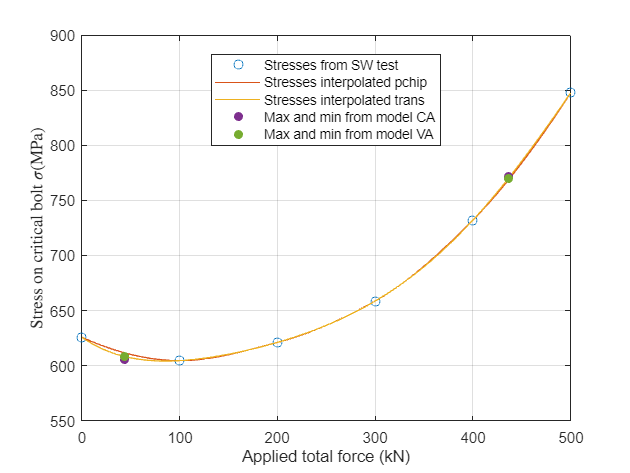


scatter(Fs, [S_min_CA, S_max_CA]/1e6,'fill', DisplayName='Max and min from model CA')
scatter(Fs, [S_min_VA, S_max_VA]/1e6, 'fill', DisplayName='Max and min from model VA')
ylim([550, 900])
xlabel('Applied total force (kN)')
ylabel('Stress on critical bolt $\sigma$(MPa)', Interpreter='latex')
grid("on")
hold off

Finding the life cyles with EC3-1-9 DC50.

N_start = 1e4;
N_DC = 2e6;
dS_DC = 50;
N_D = 5e6;
N_L = 1e8;
m1 = 3;
m2 = 5;

C1 = super(sym('C'), N_DC, dS_DC, m1) %dS_DC^m1 * N_DC;

C1 =       2.5e+11


dS_D = super(C1, N_D, sym('dS_D'), m1)

dS_D =         36.84


dS_start = super(C1, N_start, sym('dS_D'), m1)

dS_start =         292.4


C2 = super(sym('C'), N_D, dS_D, m2)

C2 =     3.393e+14


dS_L = super(C2, N_L, sym('dS_L'), m2)

dS_L =        20.236




dSs = [dS_start, dS_DC, dS_D, dS_L, dS_L];
Ns = [N_start, N_DC, N_D, N_L, 1e9];

figure(3)
loglog(Ns, dSs,'-', DisplayName='SN curve')
hold on
xlabel('Lifetime - Cycles N')
ylabel('Stress range $\Delta\sigma$(MPa)', Interpreter='latex')
ylim([10,1000])
grid("on")

estemated life

format shortg
DS = (S_max - S_min)/1e6 %converting to MPa

DS =        8.7037       168.54       158.13


% N_life = [];
for i = 1:length(DS)
    if DS(i) > dS_D
        m = m1;
        C = C1;
        disp("above knee")
    else
        m = m2;
        C = C2;
        disp("below knee")
    end
    syms N_sym; assume(N_sym, 'real'); assume(N_sym, 'positive')
    % N_eq = C == DS(i)^m * N_sym;
    % N = solve(N_eq, N_sym);
    % N_life(i) = double(N(1));
    N_life(i) = super(C, N_sym, DS(i), m);
    N_life(i)
end

below knee


ans =    6.7931e+09


above knee


ans =         52215


above knee


ans =         63230



N_life_top = N_life(1)

N_life_top =    6.7931e+09


N_life_midt = N_life(2)

N_life_midt =         52215


N_life_bot = N_life(3)

N_life_bot =         63230


N_lifes = [N_life_top, N_life_midt, N_life_bot];

scatter(N_life_top, DS(1), DisplayName="Top bolt")
scatter(N_life_midt, DS(2), DisplayName="Midt bolt")
scatter(N_life_bot, DS(3), DisplayName="Bot bolt")
legend(Location='best')


b) The structure was tested and endured 169.800 load cycles before the bolts fractured under the

above load [1]. Compare your calculations with this value.

N_test = 169800;
% dS_test = super(C1, N_test, sym('dS_D'), m1)
dS_test = DS(2) % 118%

dS_test =        168.54


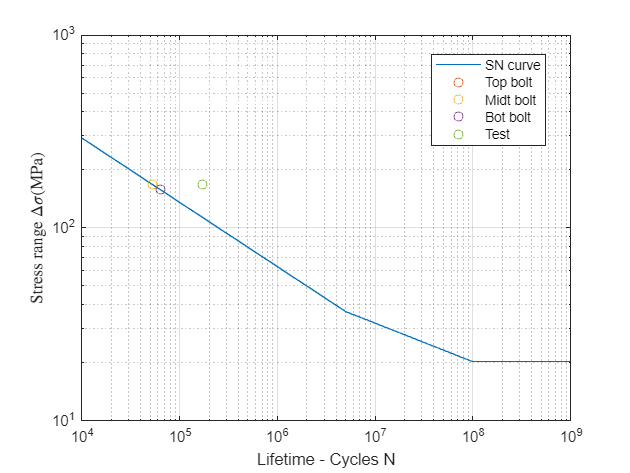

scatter(N_test, dS_test, DisplayName="Test")
hold off

Det ligger pænt over vores SN kurve. Ud fra dette ene eksempel kan man ikke sige meget men indtil vidre er SN kurven konservativ

c) Create a plot of the bolt stress as a function of the external load in the range 𝐹 = 0 − 500𝑘𝑁 for the critical bolt and explain how you could use this nonlinear transfer function for VA loading.